% Clear workspace, command window, and close all figures
clear;
clc;
close all;
% Increase graphics timeout
set(0, 'DefaultFigureCreateFcn', @(fig, ~)set(fig, 'CloseRequestFcn', @(src, ~)close(src)));

# Tuneable Parameters

% Simulation parameters
params.dt = 1;  % time step (s)
num_iterations = 100; % Number of time steps
num_vehicles = 10; % Number of vehicles 

% generate_traffic_signal_states
params.red_time = 20;   % Red light duration (s)
params.yellow_time = 3.5; % Yellow light duration (s)
params.green_time = 20; % Green light duration (s)
params.d_stop_line = 300; % Stop line position (m)

% decision model
params.D_h = 150;       % Decision distance in meters
params.T_reaction = 1.0;% Reaction time in seconds
params.p_stop = 0.7;    % Probability of stopping in the dilemma zone
params.b_max = 3.0; 
params.a = 1.0;

% IDM parameters
params.v_desired = 15;  % desired speed (m/s)
params.a_max = 1.0;     % maximum acceleration (m/s^2)
params.b = 1.5;         % comfortable deceleration (m/s^2)
params.s0 = 2.0;        % minimum gap (m)
params.T = 1.0;         % safe time headway (s)
params.delta = 4;       % acceleration exponent

% Acceleration noise
params.n_a = 0.1;       % Bound for uniform distribution U[-params.n_a, params.n_a]




#  generate_traffic_signal_states

% Generate traffic signal states
[traffic_signal_states] = generate_traffic_signal_states(num_iterations, params)

traffic_signal_states = 100×1 string array
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "green"
    "yellow"
    "yellow"
    "yellow"
    "yellow"
    "red"
    "red"
    "red"
    "red"
    "red"
    "red"


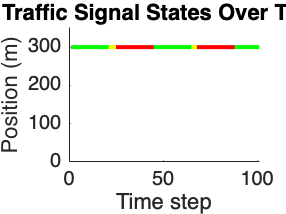

% Plot traffic light state as a horizontal line at y = d_stop_line
figure(1);
hold on;

d_stop_line = params.d_stop_line;

for k = 1:num_iterations
    if traffic_signal_states(k) == "red"
        plot([k k+1], [d_stop_line d_stop_line], 'r', 'LineWidth', 2);
    elseif traffic_signal_states(k) == "yellow"
        plot([k k+1], [d_stop_line d_stop_line], 'y', 'LineWidth', 2);
    elseif traffic_signal_states(k) == "green"
        plot([k k+1], [d_stop_line d_stop_line], 'g', 'LineWidth', 2);
    end
end

xlabel('Time step');
ylabel('Position (m)');
title('Traffic Signal States Over Time');
ylim([0 d_stop_line + 50]);
hold off;

# IDM

% Initial conditions
d = zeros(num_iterations, num_vehicles);
v = zeros(num_iterations, num_vehicles);
a_IDM = zeros(num_iterations, num_vehicles);
s = 20 * ones(1, num_vehicles);  % initial gap to the leading vehicle (m)

% Set initial positions and speeds
d(1, :) = rand(1, num_vehicles) * 100; % Random initial positions (m)
v(1, :) = rand(1, num_vehicles) * 10; % Random initial speeds (m/s)

% Simulate over time
for k = 1:num_iterations-1
    for i = 1:num_vehicles
        if i == 1
            % Leading vehicle dynamics (no vehicle in front)
            delta_v = v(k, i); % Speed difference to leading vehicle, 0 for first vehicle
            s_i = Inf; % Infinite gap for the leading vehicle
        else
            % Following vehicles
            delta_v = v(k, i-1) - v(k, i);
            s_i = d(k, i-1) - d(k, i);
        end
        a_IDM(k, i) = intelligent_driver_model(v(k, i), delta_v, s_i, params);

        % Update velocity and position using state_transition function
        current_state = [d(k, i), v(k, i), a_IDM(k, i), 0, 0]; % Assuming D and lane are not used in the current context
        next_state = state_transition(current_state, params);
        
        % Extract next state's position and velocity
        d(k+1, i) = next_state(1);
        v(k+1, i) = next_state(2);

        % Check for invalid values
        if isnan(d(k+1, i)) || isnan(v(k+1, i)) || isinf(d(k+1, i)) || isinf(v(k+1, i))
            error('Invalid value detected at iteration %d for vehicle %d.', k, i);
        end
    end
end

Invalid value detected at iteration 5 for vehicle 2.

% Display results
disp('Accelerations (a_IDM):');
disp(a_IDM);
disp('Velocities (v):');
disp(v);
disp('Positions (d):');
disp(d);

# decision

% Initialize states
d = zeros(num_iterations, num_vehicles);
v = zeros(num_iterations, num_vehicles);
T_elapsed = zeros(num_iterations, num_vehicles);
D = strings(num_iterations, num_vehicles);
S = strings(num_iterations, 1);

% Initial positions and speeds
d(1, :) = rand(1, num_vehicles) * 100; % Random initial positions
v(1, :) = rand(1, num_vehicles) * 10; % Random initial speeds

% Generate traffic signal states
[traffic_signal_states] = generate_traffic_signal_states(num_iterations, params);
S(:, 1) = traffic_signal_states;

% Simulate over time
for k = 1:num_iterations-1
    % Simulate vehicle positions and speeds (simple linear model for example)
    d(k+1, :) = d(k, :) + v(k, :);
    v(k+1, :) = v(k, :) + (rand(1, num_vehicles) - 0.5); % Random acceleration
    
    % Calculate decisions
    D(k+1, :) = decision_making(d(k, :), d(k+1, :), v(k, :), v(k+1, :), S(k), S(k+1), T_elapsed(k, :), T_elapsed(k+1, :), D(k, :), params);
end

Error: File: decision_making.mlx Line: 62 Column: 5
Illegal use of reserved keyword "end".


% Plot results
figure(3);
hold on;
colors = {'r', 'g', 'b', 'c', 'm', 'y', 'k', [0.5 0.5 0.5], [0.8 0.2 0.2], [0.2 0.8 0.2]};

for i = 1:num_vehicles
    for k = 1:num_iterations
        if D(k, i) == "stop"
            plot(k, i, 's', 'Color', colors{i}, 'MarkerFaceColor', 'r'); % Red square for stop
        elseif D(k, i) == "go"
            plot(k, i, 'o', 'Color', colors{i}, 'MarkerFaceColor', 'g'); % Green circle for go
        else
            plot(k, i, '*', 'Color', colors{i}); % Star for undecided or other states
        end
    end
end

xlabel('Time step');
ylabel('Vehicle index');
title('Vehicle Decisions Over Time');
hold off;